## 1a. Load and Extract Summary Table Values

**Objective**: Load summary tables, extract the mean, median, standard deviation (std), and interquartile range (IQR) for the first four channels.**Explanation:**

- Use `load` to read the summary tables into MATLAB.

- Extract values for mean, median, std, and IQR for the first four channels.

- Organize the extracted values into separate arrays.

## **1b. Store Values in 4x30 Matrices**

**Objective**: Organize the values into four matrices for each parameter (mean, median, std, IQR).

**Explanation:**

- Use the data from part (a) directly since it already fulfills the 4x30 requirement.


% Define the folder path containing the daily data files
folderPath = 'C:\Users\sanus\Documents\MATLAB\New folder\Loader A April Data Tables'; 

% Get a list of all files in the folder
dataFiles = dir(fullfile(folderPath, '*.mat')); % Assuming files are .mat files

% Pre-allocate matrices to store statistics for each day
numDays = length(dataFiles);
mean_matrix = NaN(4, numDays);
median_matrix = NaN(4, numDays);
std_matrix = NaN(4, numDays);
IQR_matrix = NaN(4, numDays);

% Loop through each file and compute statistics
for day = 1:numDays
    % Load the data for the current day
    dataStruct = load(fullfile(folderPath, dataFiles(day).name));
    
    % Check if the loaded data is a table and convert if necessary
    fieldNames = fieldnames(dataStruct);  % Get field names in the struct
    
    % Assume the first field in the struct is the data table
    dataTable = dataStruct.(fieldNames{1});  
    
    % Check if the data is already a table
    if istable(dataTable)
        % Convert the first four columns to an array
        numColumns = min(width(dataTable), 4);  % Ensure there are enough columns
        channels = table2array(dataTable(:, 1:numColumns));
        
        % Pad with NaN if fewer than 4 columns
        if numColumns < 4
            channels(:, end+1:4) = NaN;
        end
    else
        % If data is not a table, assume it’s already in numeric array format
        channels = dataTable(:, 1:min(4, size(dataTable, 2)));  % Limit to 4 columns
    end
    
    % Compute statistics for each channel
    mean_matrix(:, day) = mean(channels, 'omitnan');
    median_matrix(:, day) = median(channels, 'omitnan');
    std_matrix(:, day) = std(channels, 'omitnan');
    IQR_matrix(:, day) = iqr(channels);
end

disp(mean_matrix);

   51.3418   12.9487    5.4047   55.6677   62.8538   61.8120   59.5157   61.2811   66.3526   61.8268   65.4204   56.9087   57.9751   51.1877   47.5766   48.6792   41.8713   48.2567   19.5100   49.7352   57.1678   43.1441   46.2620   48.0129   54.6469   70.5163   54.1144   52.1783   55.1178
   32.9857   63.5724   58.3535   43.1864   37.6658   43.0460   33.3945   46.7450   36.1833   36.8360   35.6183   38.2631   35.1946   33.3842   34.4208   49.5168   33.5617   39.7343   32.7190   29.9612   32.6077   24.4099   23.3725   31.2762   28.4415   40.5621   37.9764   38.9878   28.7286
   31.5829   41.5308   32.2334   35.6865   30.7172   37.9149   33.5965   44.8610   37.4664   36.3080   36.3017   34.5992   32.5783   31.5676   30.7364   48.6817   30.1855   45.9825   29.5738   22.4920   32.7734   27.0362   30.0662   24.7629   34.4168   44.0483   31.6844   34.5273   32.7960
   52.3805   10.1308    6.6975   56.0031   61.7533   63.1140   61.7546   61.0374   64.5006   63.7372   66.8502   54.7627   56.2

disp(median_matrix);

   50.7583   11.0960    4.7141   56.2030   56.7499   60.9199   59.9083   49.3500   56.8917   50.0250   56.2818   47.7417   55.0538   52.0649   39.0906   44.0005   38.9564   45.7500   12.2719   48.2842   55.0000   33.0000   41.7638   42.7500   50.2250   61.3364   50.2774   49.7677   55.6327
   28.5638   71.2500   75.5000   32.6000   25.4008   26.8892   28.1758   28.2935   27.3250   28.4663   18.7780   29.0847   31.1752   19.6018   23.2386   29.9448   22.6000   32.3152   20.4268   12.3835   15.6314   12.4256   13.3174   15.9618   20.4167   24.1363   16.9959   23.4550   21.0417
   26.3410   39.5000   33.0000   23.1905   23.8560   25.5333   26.8583   25.4383   27.6618   25.1907   19.5409   22.4625   26.7000   20.7833   19.9888   27.5294   19.0167   28.4833   18.7191   12.1427   15.0453   15.4596   16.5152   13.6138   20.0833   23.4365   17.2614   21.0254   22.7654
   52.7833    5.5203    2.5149   55.9307   56.4197   60.1658   60.7833   50.2806   59.1500   50.5583   58.0028   45.8875   52.8

disp(std_matrix);

   39.4573   10.5992    4.9086   40.5095   54.3091   49.2411   46.3539   60.6812   60.4913   58.6784   59.7665   54.9745   44.8766   39.3069   42.9527   42.0525   35.1151   40.6911   28.5693   39.4907   46.7571   42.7571   41.0258   42.9471   45.5174   62.9655   45.0540   43.7346   42.1295
   30.0877   32.3677   37.7687   45.6312   45.8612   56.5717   31.8997   62.9375   36.3569   35.9528   51.6826   41.2437   30.1620   44.1246   41.5916   63.4773   38.1742   39.0859   43.6324   49.8899   49.4389   33.2690   29.8952   43.7377   30.9291   52.1410   59.7345   50.8903   32.6906
   31.3479   29.5624   22.5589   43.1990   31.9585   46.4933   34.2021   63.6328   38.3739   38.2965   50.4856   42.3229   31.9340   37.4828   37.8568   65.8619   36.5903   59.8962   35.9253   29.3378   51.2564   34.9737   39.0508   35.0586   47.0170   62.9241   42.5288   43.3219   40.2809
   39.0364   13.8398   10.2888   40.2393   51.7926   51.9674   48.8343   58.7807   54.0882   61.0149   61.2565   52.3737   43.9

disp(IQR_matrix);

   24.3030   20.5000    8.0000   30.3998   49.1105   56.8676   49.6517   41.7274   32.3755   32.2999   36.1747   49.6293   33.2567   40.8037   32.7618   46.2504   39.3853   41.5688   16.5164   20.9407   36.1235   16.6922   42.2886   31.0041   46.7168   43.9083   47.0684   50.1854   43.8249
    8.0136   46.8046   67.5665   14.9563    7.7622   15.5025   18.0633   12.4833   16.4500   11.0168    4.1537   10.8906   12.2497    3.1018   10.7971    7.4708    7.1753   11.5244   11.4601   12.0000   17.7833   10.0750    8.1667   13.2667    8.6300    6.1000    7.4333    7.1406   10.2549
    9.1847   32.9743   28.5752   15.2881    7.4756   14.9681   15.8736   11.2893    9.4750   10.3333    4.6950    4.5979    9.3886    6.3737   10.4405    9.9098    6.9064    9.3663    7.4710    9.2667   17.8500    6.9020   11.2996   12.4833    5.5654    6.4167    8.6500    8.1131    7.6545
   22.7906   10.7439    6.1550   30.9430   48.6528   58.1473   49.1612   40.3371   34.0975   31.0715   40.0236   46.9254   31.6

## **1c. Write Outlier Detection Function**

**Objective**: Create a function to identify outliers based on the IQR formula.

**Explanation:**

- The formula for detecting outliers is: 

`                                   Lower Bound``=``Q``1``−``x``⋅``I``QR `

`                                   Upper Bound``=``Q``3``+``x``⋅``I``Q``R`

             where x defaults to 1.5.

- Return a boolean vector indicating outliers.

% Define the outlier detection function
function is_outlier = detectOutliers(dataTable, x)
    if nargin < 2
        x = 1.5;
    end
    q1 = prctile( dataTable, 25);
    q3 = prctile( dataTable, 75);
    IQR_value = q3 - q1;
    is_outlier = ( dataTable > (q3 + x * IQR_value)) | ( dataTable < (q1 - x * IQR_value));
end


## **1d. Apply Function Row-Wise**

**Objective**: Apply the outlier detection function to each row of the four matrices.

**Explanation:**

- Use MATLAB's `arrayfun` or a loop to apply the function row-by-row.

% Apply outlier detection to each row (channel) of each matrix
outliers_mean = false(size(mean_matrix));

   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0



outliers_median = false(size(median_matrix));

   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0



outliers_std = false(size(std_matrix));

   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0



outliers_IQR = false(size(IQR_matrix));

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0




for i = 1:4  % For each channel
    outliers_mean(i, :) = detectOutliers(mean_matrix(i, :));
    outliers_median(i, :) = detectOutliers(median_matrix(i, :));
    outliers_std(i, :) = detectOutliers(std_matrix(i, :));
    outliers_IQR(i, :) = detectOutliers(IQR_matrix(i, :));
end

disp(outliers_mean);
disp(outliers_median);
disp(outliers_std);
disp(outliers_IQR);


## **1e. Compute “Outlierness” of Each Day**

**Objective**: Calculate the sum of outlier occurrences for each day.

**Explanation:**

- Sum the boolean matrices column-wise.

- If all results are zero, modify `x``x`x and repeat.

% Compute the total "outlierness" for each day
outlierness_mean = sum(outliers_mean, 1);
outlierness_median = sum(outliers_median, 1);
outlierness_std = sum(outliers_std, 1);
outlierness_IQR = sum(outliers_IQR, 1);


     0     3     3     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     2     0     0     0     0     0     0     0     0     0     0



% Combine all outlier counts per day

     0     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0



total_outlierness = outlierness_mean + outlierness_median + outlierness_std + outlierness_IQR;

     0     2     2     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0



     0     2     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% Adjust x if needed and rerun detection if total outlierness is zero

     0    11    11     0     0     0     0     0     0     0     0     0     0     0     0     2     0     1     4     0     0     0     0     0     0     0     0     0     0



if all(total_outlierness == 0)
    disp('No outliers detected with x = 1.5, adjusting x...');
    % Set new value for x and re-run outlier detection if needed
end
disp(outlierness_mean);
disp(outlierness_median);
disp(outlierness_std);
disp(outlierness_IQR);
disp(total_outlierness);


**Discussion:**

If `x``=``1.5` fails to detect outliers, it implies a tighter range for identifying anomalies. Adjusting `x` broadens the acceptable range, making it easier to flag anomalies in extreme datasets.

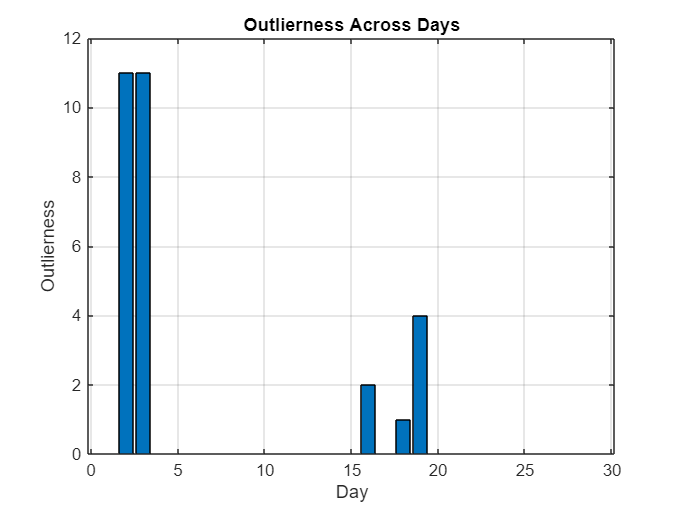

% Visualize results

figure;
bar(total_outlierness);
xlabel('Day');

Tatal Outlierness values:


ylabel('Outlierness');

     0    11    11     0     0     0     0     0     0     0     0     0     0     0     0     2     0     1     4     0     0     0     0     0     0     0     0     0     0



title('Outlierness Across Days');
grid on;

% Print results
fprintf('Tatal Outlierness values:\n');
disp(total_outlierness);
